# Module 1: MATLAB Interface and Scripts

## 1. Overview

MATLAB ("MATrix LABoratory") is a popular programming lauguage that have been using extensively in engineering, mathematics, and science. It provides a user-friendly platform for complex mathematical computations, data analysis, and visualization. 

#### Examples

- Denoise noisy doppler signal ([https://www.mathworks.com/help/signal/ug/denoise-noisy-doppler-signal.html](https://www.mathworks.com/help/signal/ug/denoise-noisy-doppler-signal.html))

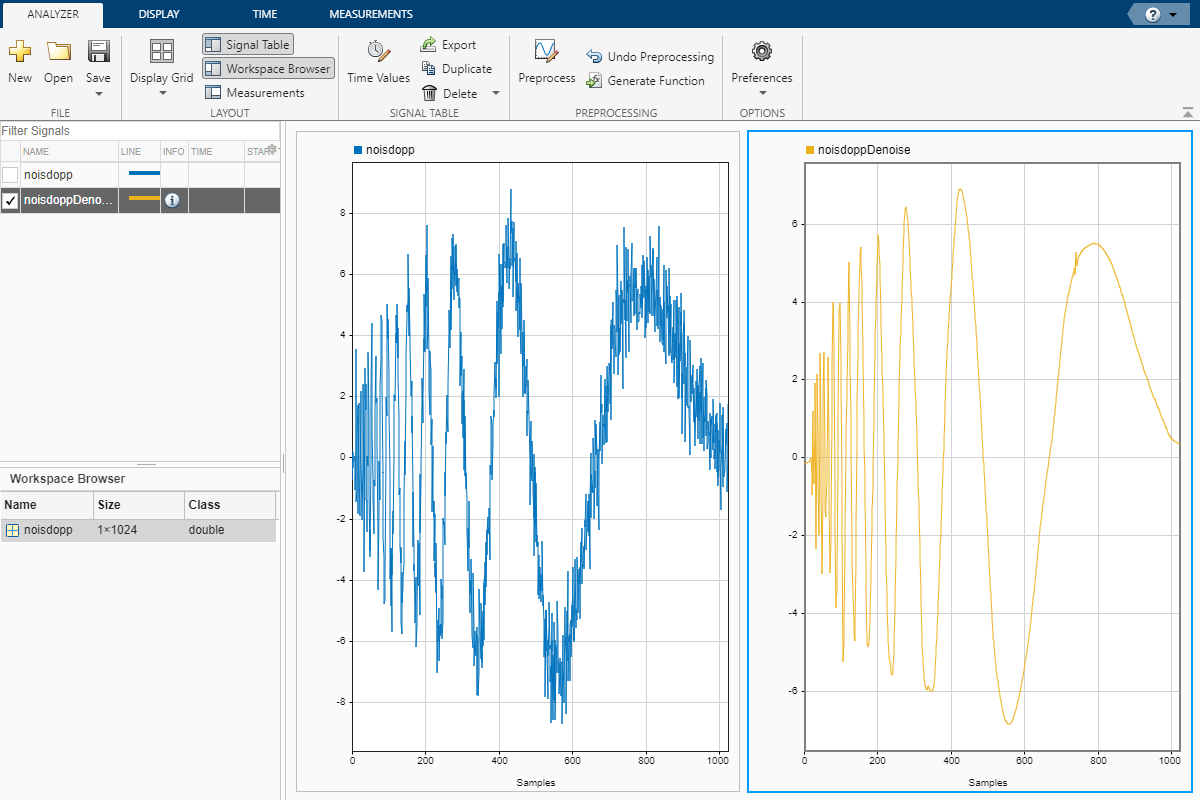

- Modeling the brain tumor growth ([Han, Lifeng, et al. "Patient-specific parameter estimates of glioblastoma multiforme growth dynamics from a model with explicit birth and death rates." Mathematical biosciences and engineering: MBE 16.5 (2019): 5307.](https://www.aimspress.com/article/10.3934/mbe.2019265))

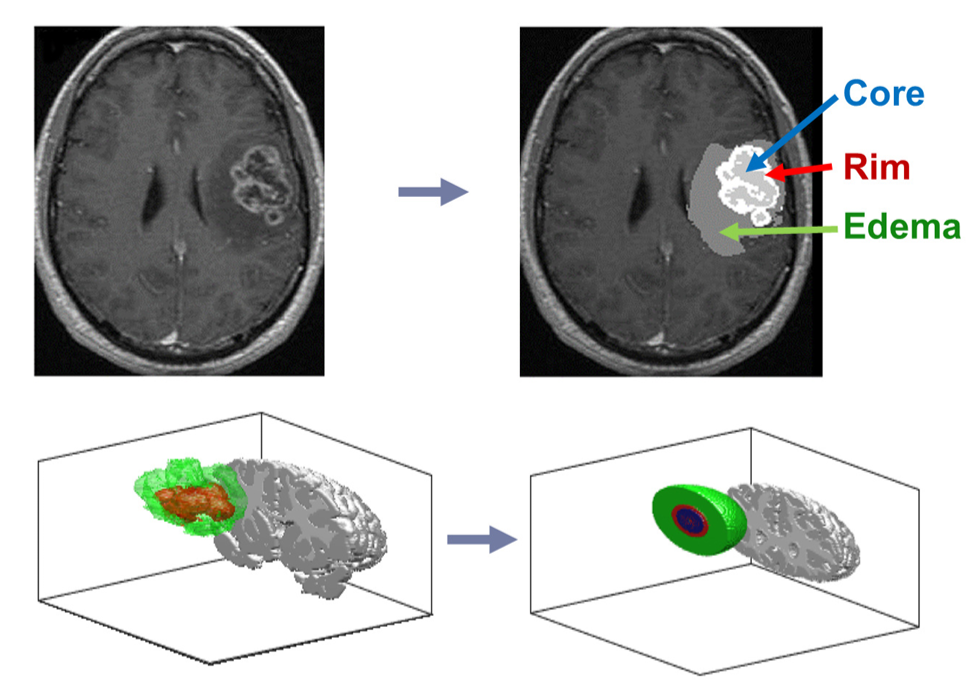

## 2. MATLAB Interface

The MATLAB interface is the graphical user interface (GUI) and command-line environment that you can interact with when working in MATLAB.

When the application is initiated, you can see the following major components in the interface:

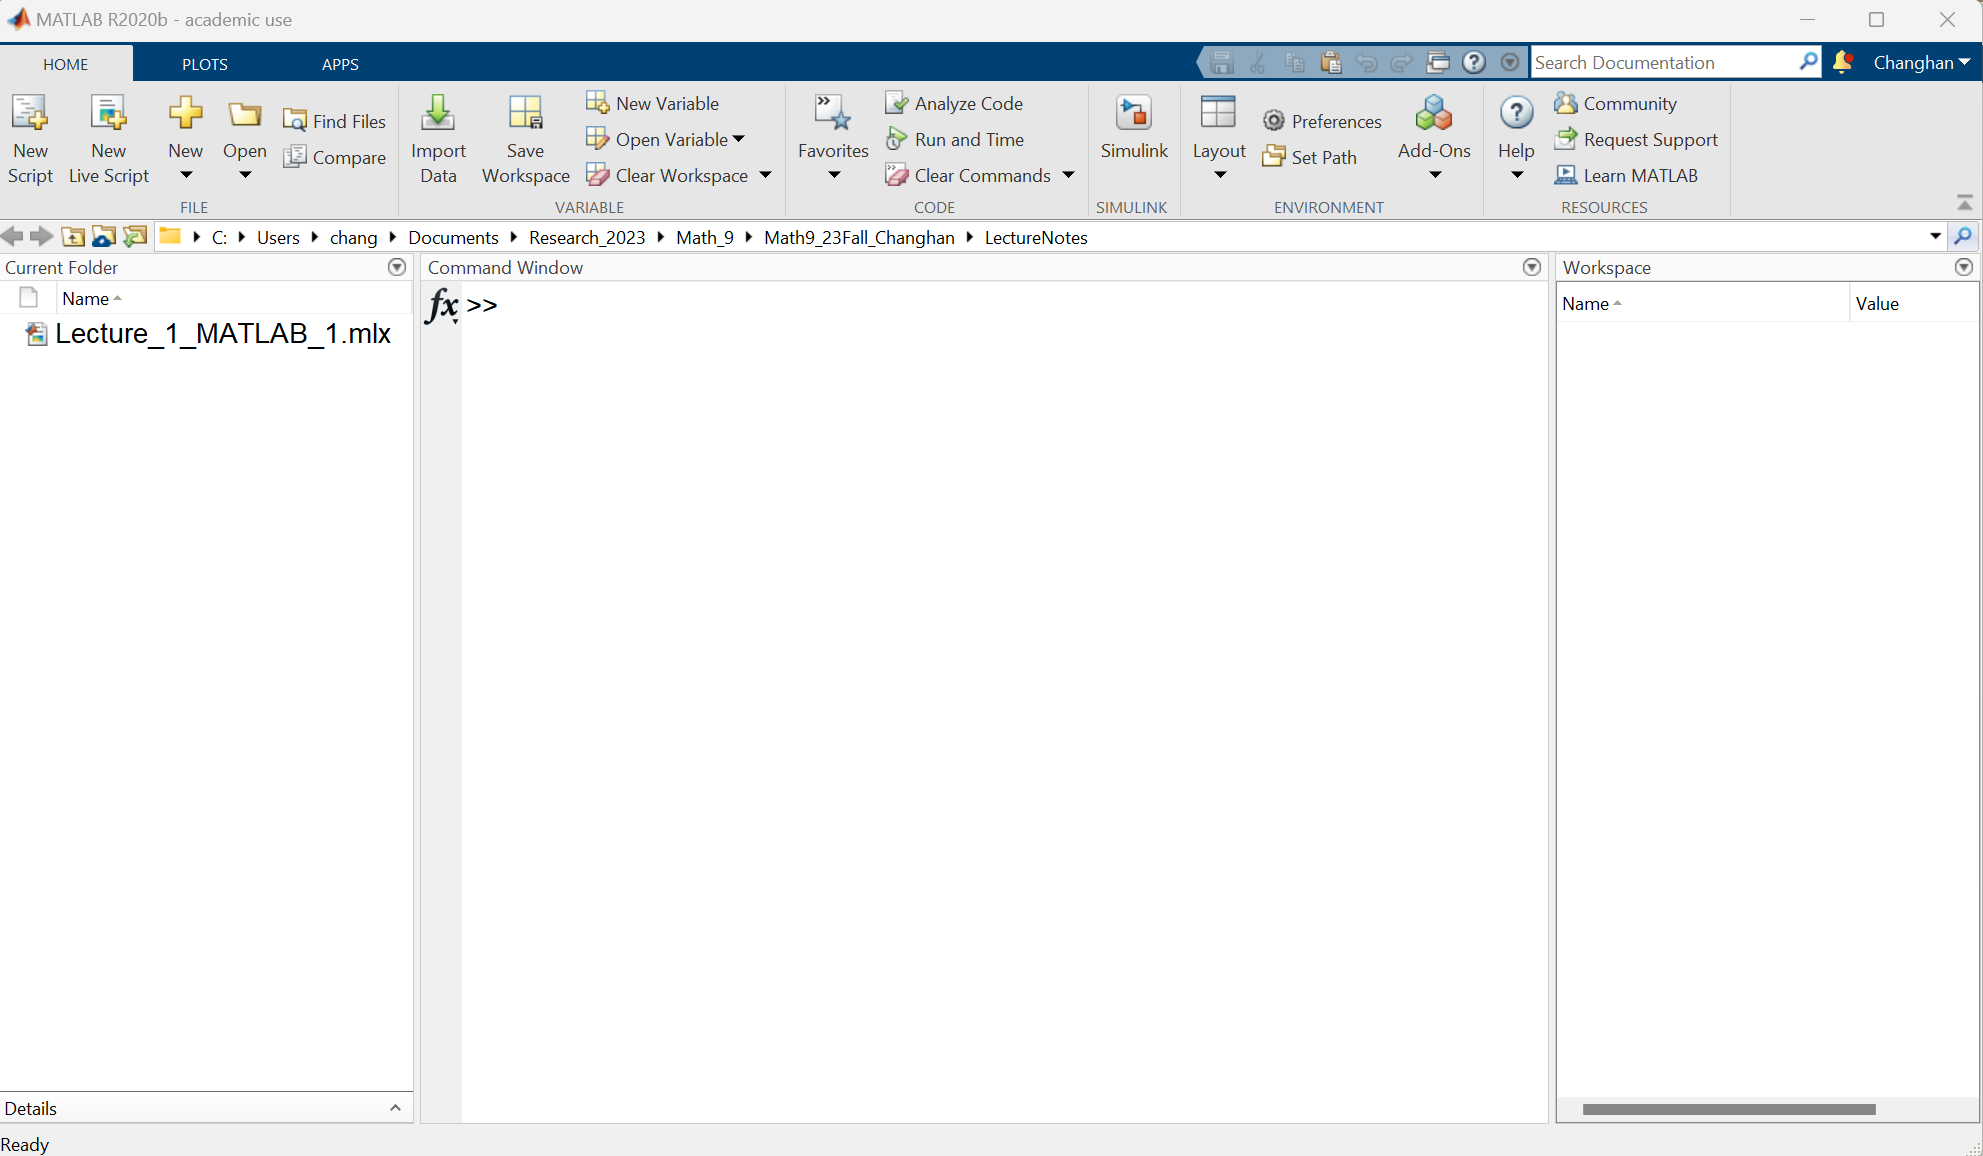

1) **"Toolstrip"**, a toolbar that provides access to common MATLAB tasks, including opening files, accessing documentation, and managing add-ons and toolboxes.

2) **"Plots"**, some useful plotting functions for creating 2D and 3D plots and visualizations. You can also customize plots, add labels, legends, and annotations using the plotting tools.

3) **"Apps"**, for some specific functions, MATLAB has built-in apps so that you can use directly, like data fitting, image processing, and signal analysis. 

4) **"Current Folder"**, this panel shows the files and folders in the current directory and you can navigate and manage the MATLAB files and scripts here. You can set the initial position in the "Preferences", or otherwise it will automatically show the folder in last Matlab session.

5) **"Command Window"**, interactive command-line interface where you can enter and execute MATLAB commands. You can perform calculations, run scripts, and see the results immediately. Some most frequently used commands and tricks include:

- `help `followed by command name:  to display the usage/description of certain command

- `lookfor `followed by keyword: to diaply relevant commands to the keyword

- `clc` : to clear the command window

- press the "tab" key on keyboard: autocomplete the command

- press the "up-arrow" key on keyboard: command history 

- output without varaibale names assigned is saved in variable `ans`

6) **"Workspace",** displays all the variables you can use in current Matlab session. It provides details about the variables' names, dimensions, and values.  Some most frequently used commands and tricks include:

- `clear: `remove variables. To selectively remove, follow by certain variable names

- `save`:  followed by a file name, save all the varaibles in workspace to that file (suffix with .mat) for later re-use

- `load`: import the variables in certain .mat file

- `whos: display the workspace in command line`

- double-click or right-click the varaibles in workspace window

7) **"Editor"** , where you can create, edit, and debug MATLAB scripts and functions in this environment (we will see more examples soon). 

### ***In-class Exercise 1***

Compute the value of $y$ when $x=2
$, where $y=(sin(x))^2sin(x^2)x^2x$,  in the command window:

- define `variables:`$x=2
$ ;

- assign the variable named "y`"` with the value of $(sin(x))^2sin(x^2)x^2x$ ; *(What is *$sin(x)$*in MATLAB? Check out *[this page](https://www.mathworks.com/help/matlab/ref/sin.html)*!)*

- what is the value of $(sin(x))^2sin(x^2)x^{2x}$ ?

x = 2;
y = (sin(x))^2*sin(x^2)*x^2*x

y = -5.0059

(sin(x))^2*sin(x^2)*x^(2*x)

ans = -10.0119

### ***In-class Exercise 2***

Recall the definition of derivative as $f'(x)=\lim_{h\to0}\frac{f(x+h)-f(x)}{h}$. Follow the instructions below to implement the **numerical differentiation** for $f(x)=x^2\sin(x)$ at $x=4
$ in the command window:

- define` variables: `${h=10}^{-6}$ and $x=4
$ ; *(What is *${\textrm{10}}^{-6}$* in MATLAB? *[*This page*](https://www.mathworks.com/help/matlab/arithmetic-operators.html)* may be helpful.) *

- assign the variable named "`der"` with the value of accuate derivative at $x=4
$ ;

- assign the variable named "`der_appr"` with value of the finite difference $\frac{f(x+h)-f(x)}{h}$ ; 

- assign the variable named "`err"` with the value  "`der_appr" `minus` "der";`

- save the current workspace to the file named "der_data.mat" ;

- clear all the variables.

**Hint: **When confonted with anything unfamiliar in programming, you can always try the **help** function in MATLAB or google them. Memorizing the most frequent operators is our requirement.

h = 1e-6;
x = 4;
der = 2*x*sin(x) + x^2*cos(x);
der_appr = ((x+h)^2*sin(x+h) - x^2*sin(x))/h;
err = der_appr - der

err = 6.6739e-08

save('der_data')
clear all

## 3. MATLAB Scripts

Programming time! A MATLAB script can be understood as **the collection of sequential single-line commands** to perform more complicated tasks. 

### **3.1 Plain Scripts (.m files)**

- To **edit** a script file, you can either: **1)** type edit followed by file name in the command window or **2)** double-click the file in the current folder window. 

- To **create** a new script file, you can also find the one-click button in "**Home**" at the top toolstrip. Once a script is open, more tools are in the "**Editor**" at the top toolstrip (including **save**).

- To **run **a script file, you can either **1)** type the file name in command window (without the .m sffuix), or **2)** click the "Run" button in the top of editor. The varaibles created during script running are saved in workspace.

- In the script file, **1)** use **semicolon(;)** to suppress output of certain line **2)** use `disp` function to display the value of certain item to the screen when running and **3)** use % to write **comments** in codes

- More complicated sripts include matlab **functions** (have input and output), and the one with **control flows** (will be introduced in detail in later lectures).

***Example 1: Math9Lec1_Example1.m***

***Example 2: Math9Lec1_Example2.m***

[sphere](https://www.mathworks.com/help/matlab/ref/sphere.html)`:`` [X,Y,Z] = sphere(n)` returns the *x*-, *y*-, and *z*- coordinates of a sphere with a radius equal to `1` and `n`-by-`n` faces. The function returns the *x*-, *y*-, and *z*- coordinates as three `(n+1)`-by-`(n+1)`matrices.

[surf:](https://www.mathworks.com/help/matlab/ref/surf.html) surface plot function. `surf(X,Y,Z)` creates a three-dimensional surface plot, which is a three-dimensional surface that has solid edge colors and solid face colors. The function plots the values in matrix `Z` as heights above a grid in the *x*-*y* plane defined by `X` and `Y`. The color of the surface varies according to the heights specified by `Z`.

### **3.2 Live Scripts (.mlx files)**

- **You are currently in a live script file!** Live scripts allow users to view and interact with both code and output and can include formatted text, equations, and images -- it is helpful to communicate and share results with others

- **Press ctrl(cmd in mac os) and +/-** simutanesouly to zoom in/out the script. More display options can be found in the "VIEW" button of top tool strip (for example, split the views and see multiple files at one time).

- Live scripts can be saved as pdf or word.

- Two major components in live scripts include **text** and **code. **Compared with plain script .m file, the text in live script can have more fancy formats than the comments, and the code can directly display the output in the script, instead of in the command line or sepate figure window. To delete code and the output, just select them all and then press "delete" on keyboard.

- Live scripts can be discomposed into sections and runned seprately -- by inserting the **section break (either click or type %%)**. Sections already runned are asscociated with blue bars on the left, and sections with unexecuted chagnes are with the vertical striping. 

- To adjust the format of output, explore the"VIEW" page of top tool strip. To remove all the outputs, click "Clear all Output" button in the "VIEW" page.

- With more outputs in the livescript, it may take longer time to save -- please be patient.

Below is the example of a code section in a live script:

% Create and plot a sphere with radius r.
[x,y,z] = sphere(50);       % Create a unit sphere.
r = 2;
surf(x*r,y*r,z*r);       % Adjust each dimension and plot.
axis equal              % Use the same scale for each axis. 

### ***In-Class Excerse 3***

- create a new section below by insert the section break;

- type function $f(x)=x^2\sin(x)$;

- Insert a code section, and define` variables `$x=4
$ ;

- in the same code section, use a control bar (Min = 0, Max = 1, Step = 0.001) to define` variables `$h
$ ; run the section;

- insert another code section, assign the variable named "`der"` as the derivative of $f(x)=x^2\sin(x)$ ; run the section;

- insert another code section, assign the variable named "`der_appr"` as the finite difference $\frac{f(x+h)-f(x)}{h}$ ; run the section;

- insert another code section, assign the variable named "`err"` with the value  "`der_appr" `minus` "der"`; run the section;

**Hint: **The equations can be typed in the "INSERT" page of tool strip -- either interactively (like in MS Word) or by Latex expressions. If you want to use Latex, please refer [here](https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html).


$$f(x)=x^2\sin(x)$$


h =0.271;
x = 4;
der = 2*x*sin(x)+x^2*cos(x)

der = -16.5127

der_appr = ( (x+h)^2*sin(x+h) - x^2*sin(x) )/h

der_appr = -16.1783

err = der_appr-der

err = 0.3344

## 4. Other useful links

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h](https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG](https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG) 